# Initializing

% Initializing path of HDF5 file
clear all;
rootpath= initialize_root_path; 
fileNameStr = [rootpath,'energy-height-conversion/PFISR_Energy_Spectra/Data/DataFile_2008_1.h5'];

% Initializing GeoData class
% initialize_geodata([rootpath,'energy-height-conversion\GeoDataMATLAB\']);


## Extracting data

pfisrGD = GeoData(@readMadhdf5,fileNameStr,{'popl'});

PFISR data



% Change the log electron density to linear density
antilog = @(ex,base)(base.^ex);
pfisrGD.changedata('popl','ne',antilog,{10});
% pfisrGD.interpolate(pfisrGD.dataloc,'Cartesian','natural');

% Removing NANs
data.electronDensity = pfisrGD.data.ne;
data.time = unix_to_matlab_time(pfisrGD.times(:,1));
nBeams=26;
nData = length(data.electronDensity(:,1));
for itime=1:1:length(data.time)
    for iBeam = 1:1:26
        data.electronDensity(iBeam:nBeams:nData,itime)...
            = interp_nans(data.electronDensity(iBeam:nBeams:nData,itime));
    end
end
pfisrGD.data.ne = data.electronDensity;

## Converting coordinates to Geodetic

% [cartCoords(:,1),cartCoords(:,2),cartCoords(:,3)] = sph2cart(degtorad(pfisrGD.dataloc(:,2)),degtorad(pfisrGD.dataloc(:,3)),pfisrGD.dataloc(:,1));
az=pfisrGD.dataloc(:,2);
elev=pfisrGD.dataloc(:,3);
slant=pfisrGD.dataloc(:,1);
[yNorth, xEast, zDown] = aer2ned(az,elev,slant);
%figure; plot(xEast(1:26),yNorth(1:26),'o');
lat0 = 65.126;
lon0 = -147.47;
height = 0.689;
[geodeticCoords(:,1),geodeticCoords(:,2),geodeticCoords(:,3)] = ned2geodetic(yNorth,xEast,zDown,lat0,lon0,height,wgs84Ellipsoid('km'));

## Magnetic field aligned coordinates

minTimeStr = '26-Mar-2008 08:00';
maxTimeStr = '26-Mar-2008 12:30';
thisAltitude = 60; % in Km
magBeamNo = 1;
pfisrGDmag = copy(pfisrGD);
pfisrGDmag.data.ne = data.electronDensity;
[ pfisrGDmag, magcoords, atTime, atAltitude] = geodata_magnetic_field_interpolation...
    ( pfisrGDmag, minTimeStr, maxTimeStr, thisAltitude, magBeamNo);

Interpolating parameter ne, 1 of 1
	Interpolating time 1 of 132
	Interpolating time 2 of 132
	Interpolating time 3 of 132
	Interpolating time 4 of 132
	Interpolating time 5 of 132
	Interpolating time 6 of 132
	Interpolating time 7 of 132
	Interpolating time 8 of 132
	Interpolating time 9 of 132
	Interpolating time 10 of 132
	Interpolating time 11 of 132
	Interpolating time 12 of 132
	Interpolating time 13 of 132
	Interpolating time 14 of 132
	Interpolating time 15 of 132
	Interpolating time 16 of 132
	Interpolating time 17 of 132
	Interpolating time 18 of 132
	Interpolating time 19 of 132
	Interpolating time 20 of 132
	Interpolating time 21 of 132
	Interpolating time 22 of 132
	Interpolating time 23 of 132
	Interpolating time 24 of 132
	Interpolating time 25 of 132
	Interpolating time 26 of 132
	Interpolating time 27 of 132
	Interpolating time 28 of 132
	Interpolating time 29 of 132
	Interpolating time 30 of 132
	Interpolating time 31 of 132
	Interpolating time 32 of 132
	Interpolating

## Removing NANs

dataMag.electronDensity = pfisrGDmag.data.ne;
dataMag.time = unix_to_matlab_time(pfisrGDmag.times(:,1));
nBeams=26;
nData = length(dataMag.electronDensity(:,1));
for itime=1:1:length(dataMag.time)
    for iBeam = 1:1:26
        dataMag.electronDensity(iBeam:nBeams:nData,itime)...
            = interp_nans(dataMag.electronDensity(iBeam:nBeams:nData,itime));
    end
end
pfisrGDmag.data.ne = dataMag.electronDensity;

## Plotting magnetically interpolated density

[geodeticMagCoords(:,1),geodeticMagCoords(:,2),geodeticMagCoords(:,3)] = ned2geodetic(magcoords(:,2),magcoords(:,1),-magcoords(:,3),lat0,lon0,height,wgs84Ellipsoid('km'));
dataMag.electronDensity=pfisrGDmag.data.ne;
dataMag.time = unix_to_matlab_time(pfisrGDmag.times(:,1));
% thisTime = '26-Mar-2008 11:46';
% [timeNo] = find_time(dataMag.time, thisTime);

% figure;
% plot_2D_density_slice_geodetic...
%     (dataMag, geodeticMagCoords, timeNo, 120, true);
% colormap(inferno);
% colorbar;
% figure;
% plot_2D_density_slice_geodetic...
%     (dataMag, geodeticMagCoords, timeNo, 120, false, [64.8,66], [-148.5,-145.9]);
% colormap(inferno);
% colorbar;


## Calculating conductivity

for itime=1:1:length(dataMag.time)
    for iBeam=1:1:nBeams
        avgLat      = mean(geodeticMagCoords(iBeam:nBeams:nData,1));
        avgLon      = mean(geodeticMagCoords(iBeam:nBeams:nData,2));
        altitude    = geodeticMagCoords(iBeam:nBeams:nData,3);
        if iBeam<2
            [altitudeNo] = find_altitude( altitude, 80);
        end
        altStart=iBeam+nBeams*(altitudeNo-1);
      
        if itime==1
            conductanceLat = geodeticMagCoords(altStart:nBeams:nData,1);
            conductanceLon = geodeticMagCoords(altStart:nBeams:nData,2);
            conductanceAlt = geodeticMagCoords(altStart:nBeams:nData,3);
            nBeamConductance = length(conductanceAlt);
            dataMag.conductanceCoords(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,1) = conductanceLat;
            dataMag.conductanceCoords(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,2) = conductanceLon;
            dataMag.conductanceCoords(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,3) = conductanceAlt;
        end  
        
        conductanceData = get_conductivity_v1(conductanceAlt,...
            dataMag.electronDensity(altStart:nBeams:nData,itime),avgLat,avgLon,dataMag.time(itime));
     
        dataMag.sigma_H(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,itime) = conductanceData.sigma_H;
        dataMag.sigma_P(1+(iBeam-1)*nBeamConductance:1:nBeamConductance*iBeam,itime) = conductanceData.sigma_P;
        
        
    end
end


## Plotting conductivity

% thisTime = {'26-Mar-2008 11:40','26-Mar-2008 11:46','26-Mar-2008 11:48','26-Mar-2008 11:55','26-Mar-2008 12:00'};
% for itime=1:1:length(thisTime)
%     timeNo(itime) = find_time(dataMag.time, thisTime(itime));
% end
% 
% thisAltitude=[140,120,100,85];
% 
% hFig=figure;
% p=panel();
% p.pack(1);
% panelSize = 50;
% demargin = 4;
% p(1).pack(4,5);
% p.marginleft = 25;
% p.marginright = 10;
% p(1).de.margin = demargin;
% p.select('all');
% resize_figure(hFig,215.9,279.4);
% plot=p(1);
% p(1).title('Hall conductivity \sigma_H [log_1_0 S/m]');
% colorbar('Position',[0.95,0.15,0.01,0.75]);
% cmin = -5.5; cmax=-3.5;
% caxis([cmin cmax]);
% for itime=1:1:length(thisTime)
%     100*itime/length(thisTime)
%     F = scatteredInterpolant(dataMag.conductanceCoords(:,1),...
%         dataMag.conductanceCoords(:,2),...
%         dataMag.conductanceCoords(:,3),...
%         dataMag.sigma_H(:,itime), 'nearest', 'none');
%     
%     for ialtitude=1:1:length(thisAltitude)
%         
%         plot(ialtitude,itime).select();
%         colormap(inferno);
%        
%         if itime==1
%              text(-0.6,0.5,[num2str(thisAltitude(ialtitude)),' km'],'Units','normalized','FontWeight','bold');
%         end
%         
%         if ialtitude==1
%              text(0.05,1,[datestr(dataMag.time(timeNo(itime)),'HH:MM:SS'),' UT'],'Units','normalized','FontWeight','bold');
%         end
%         
%         plot_2D_conductivity_slice_geodetic_faster...
%                     (F, dataMag.conductanceCoords, thisAltitude(ialtitude), true, [64.8,65.7],[-148.2, -146.5]);
%     
%         caxis([cmin cmax]);
%         
%     end
% end


## Integrated conductivity

integratedData = integrate_conductivity(dataMag,nBeams, 90);
% F1 = scatteredInterpolant(integratedData.lat,...
%         integratedData.lon,...
%         ones(size(integratedData.lon)).*integratedData.projectionAltitude,...
%         integratedData.sigma_H(:,itime), 'nearest', 'none');

growthPhase = {'26-Mar-2008 11:03:33', '26-Mar-2008 11:07:40','26-Mar-2008 11:15:56', '26-Mar-2008 11:20:04','26-Mar-2008 11:24:11'}

growthPhase = 1×5 cell array
    {'26-Mar-2008 11:03:33'}    {'26-Mar-2008 11:07:40'}    {'26-Mar-2008 11:15:56'}    {'26-Mar-2008 11:20:04'}    {'26-Mar-2008 11:24:11'}


quietPhase = {'26-Mar-2008 10:03:43', '26-Mar-2008 10:07:50','26-Mar-2008 10:16:05', '26-Mar-2008 10:20:13','26-Mar-2008 10:24:21'}

quietPhase = 1×5 cell array
    {'26-Mar-2008 10:03:43'}    {'26-Mar-2008 10:07:50'}    {'26-Mar-2008 10:16:05'}    {'26-Mar-2008 10:20:13'}    {'26-Mar-2008 10:24:21'}


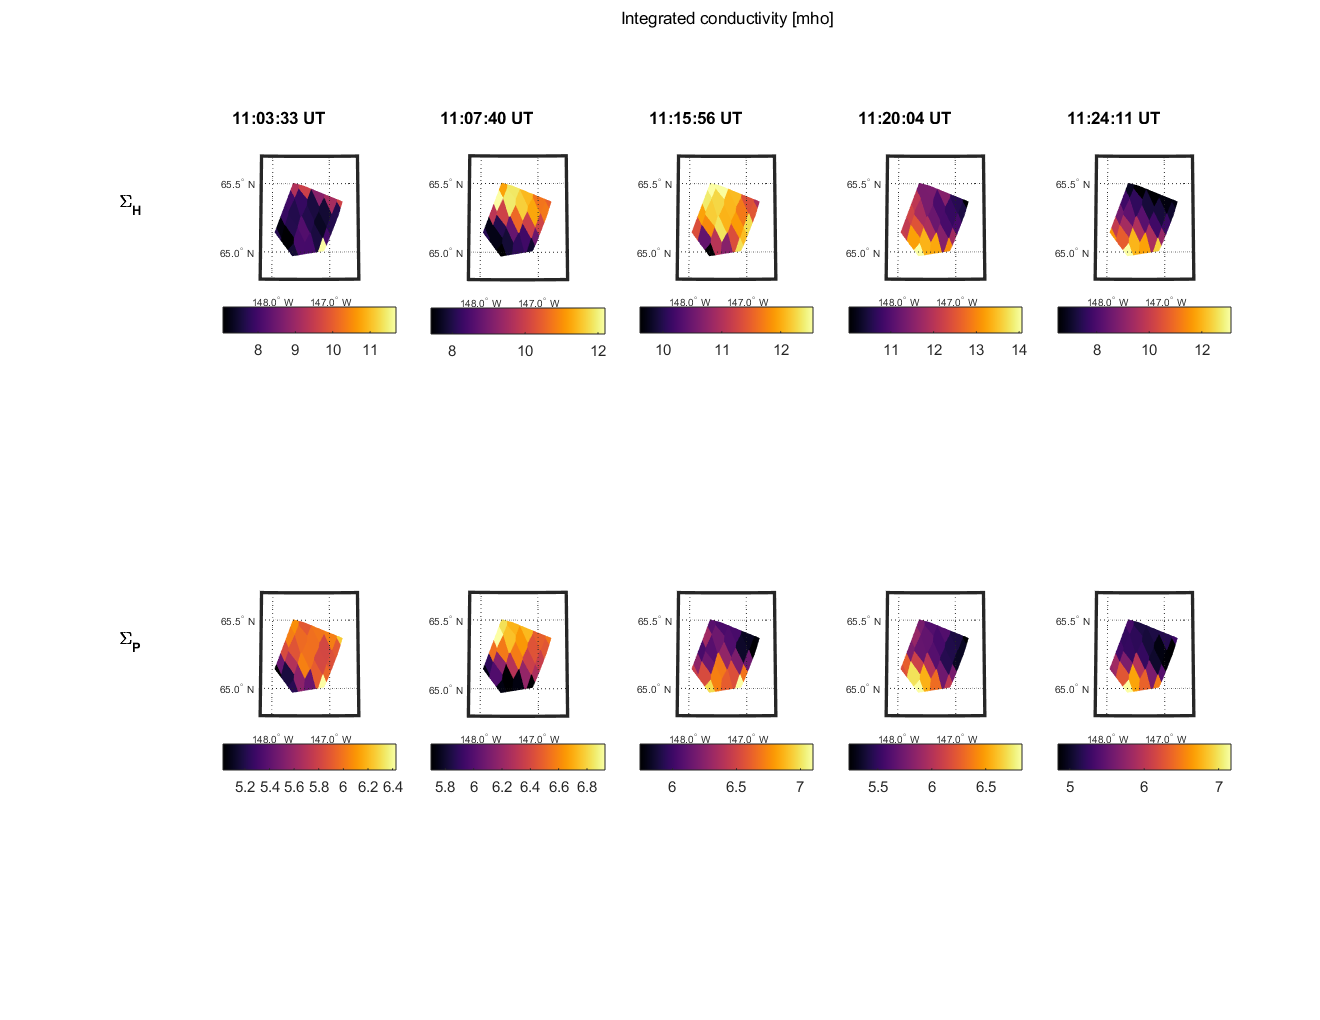

ans = 20

ans = 40

ans = 60

ans = 80

ans = 100

ans = 20

ans = 40

ans = 60

ans = 80

ans = 100

expansionPhase ={'26-Mar-2008 11:40','26-Mar-2008 11:46','26-Mar-2008 11:48','26-Mar-2008 11:55','26-Mar-2008 12:00'};
thisTime = growthPhase;
for itime=1:1:length(thisTime)
    timeNo(itime) = find_time(dataMag.time, thisTime(itime));
end
% 
% thisAltitude=[140,120,100,85];
% 
hFig=figure;
p=panel();
p.pack(1);
panelSize = 50;
demargin = 4;
p(1).pack(2,5);
p.marginleft = 25;
p.marginright = 10;
p(1).de.margin = demargin;
p.select('all');
resize_figure(hFig,215.9,279.4);
plot=p(1);
p(1).title('Integrated conductivity [mho]');
% colorbar('Position',[0.95,0.15,0.01,0.75]);
% cmin = 1; cmax=68;
% caxis([cmin cmax]);
for iconductivity=1:1:2
    for itime=1:1:length(thisTime)
    100*itime/length(thisTime)
%     F = scatteredInterpolant(dataMag.conductanceCoords(:,1),...
%         dataMag.conductanceCoords(:,2),...
%         dataMag.conductanceCoords(:,3),...
%         dataMag.sigma_H(:,itime), 'nearest', 'none');
%     
    
%         
        plot(iconductivity,itime).select();
        colormap(inferno);
%       
        if iconductivity==1
            if itime==1             
             text(-0.6,0.5,'\Sigma_H','Units','normalized','FontWeight','bold');
            end
            plot_2D_integrated_conductivity_map(integratedData,'H', timeNo(itime), true, [64.8,65.7],[-148.2, -146.5]);
            text(0.05,1,[datestr(dataMag.time(timeNo(itime)),'HH:MM:SS'),' UT'],'Units','normalized','FontWeight','bold');
            
        end
        if iconductivity==2
            if itime==1             
             text(-0.6,0.5,'\Sigma_P','Units','normalized','FontWeight','bold');
            end
            plot_2D_integrated_conductivity_map(integratedData,'P', timeNo(itime), true, [64.8,65.7],[-148.2, -146.5]);
        end
        
  
        colorbar('southoutside');
%         caxis([cmin cmax]);
%         
    end
end

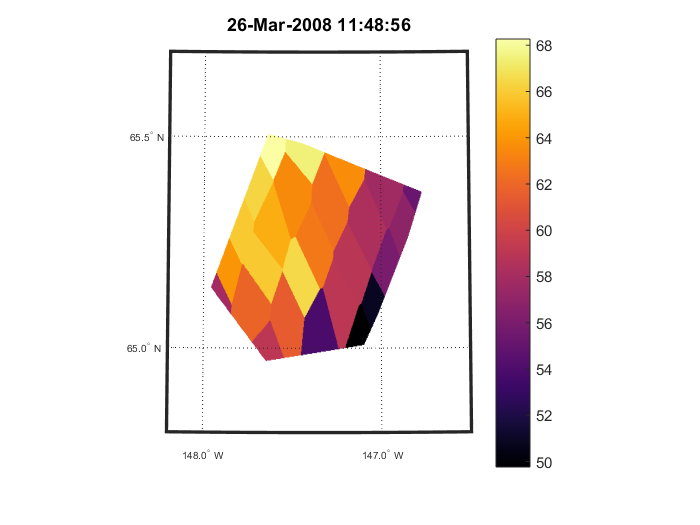


figure;
    t=5;
    plot_2D_integrated_conductivity_map(integratedData,'H', t, true, [64.8,65.7],[-148.2, -146.5]);
    colormap(inferno);
    colorbar;
    title(datestr(integratedData.time(t)));

%     caxis([10 20]);